# Study case: Clamped-free beam

## 1 Introduction

The dynamic response of a 100 m high sclamped-free steel beam is studied. Simulated time series are used, where the first three eigenmodes have been taken into account. More precisely, the acceleration response to white noise excitation is used here. The simulated data are generated with the central difference method [1], and the eigenmodes/eigenfrequencies are generated using [2]. A modal damping ratio of 0.005 for every mode is used. These parameters are considered as the "target modal parameters".

The purpose of this example is to use the AFDD to retrieve the eigenfrequencies, the mode shapes, and the modal damping ratio from Ambient vibrations analysis. This is more challenging than the classical response to impulse load, but also more common for large civil engineering structures.

The most challenging task is the estimation of the modal damping ratio from ambient vibrations data (higher sensitivity to measurement noise). Before a systematic analysis, the parameters used in the AFDD method have to be "tuned", i.e. manually tested, so that we extract the proper modal parameters. This operation is rather common in Structural Health Monitoring.

We use here two approaches:

-  Manual selection of the eigenfrequencies using the Matlab code, introduced by [3], where a friendly user-interface is proposed.

-  Automatic peak-picking of the eigenfrequencies by using the Matlab code, developed by [4], which worked much better than the function findpeaks.

#### References

[1] [https://se.mathworks.com/matlabcentral/fileexchange/55557-modal-parameters-identification-from-ambient-vibrations--sdof](https://se.mathworks.com/matlabcentral/fileexchange/55557-modal-parameters-identification-from-ambient-vibrations--sdof)

[2][ https://se.mathworks.com/matlabcentral/fileexchange/52075-eigen-value-calculation-of-a-continuous-beam--transverse-vibrations](https://se.mathworks.com/matlabcentral/fileexchange/52075-eigen-value-calculation-of-a-continuous-beam--transverse-vibrations)

[3] [https://se.mathworks.com/matlabcentral/fileexchange/50988-frequency-domain-decomposition--fdd](https://se.mathworks.com/matlabcentral/fileexchange/50988-frequency-domain-decomposition--fdd)

[4] [https://se.mathworks.com/matlabcentral/fileexchange/42927-pickpeaks-v-select-display](https://se.mathworks.com/matlabcentral/fileexchange/42927-pickpeaks-v-select-display)

## 2 Application of the function AFDD: Manual procedure

This procedure has the advantage to be easier if one has only one sample. The peak-picking method is straightforward, and lead to accurate results. However, if multiple samples have to be analysed, the manual procedure becomes cumbersome. For more details, see [3]

Peak selection procedure
a: Draw rectangles around peaks while holding left click
b: Press "Space" key to continue the peak selection
c: Press "any other key" if you have selected a peak by mistake and want to ignore it


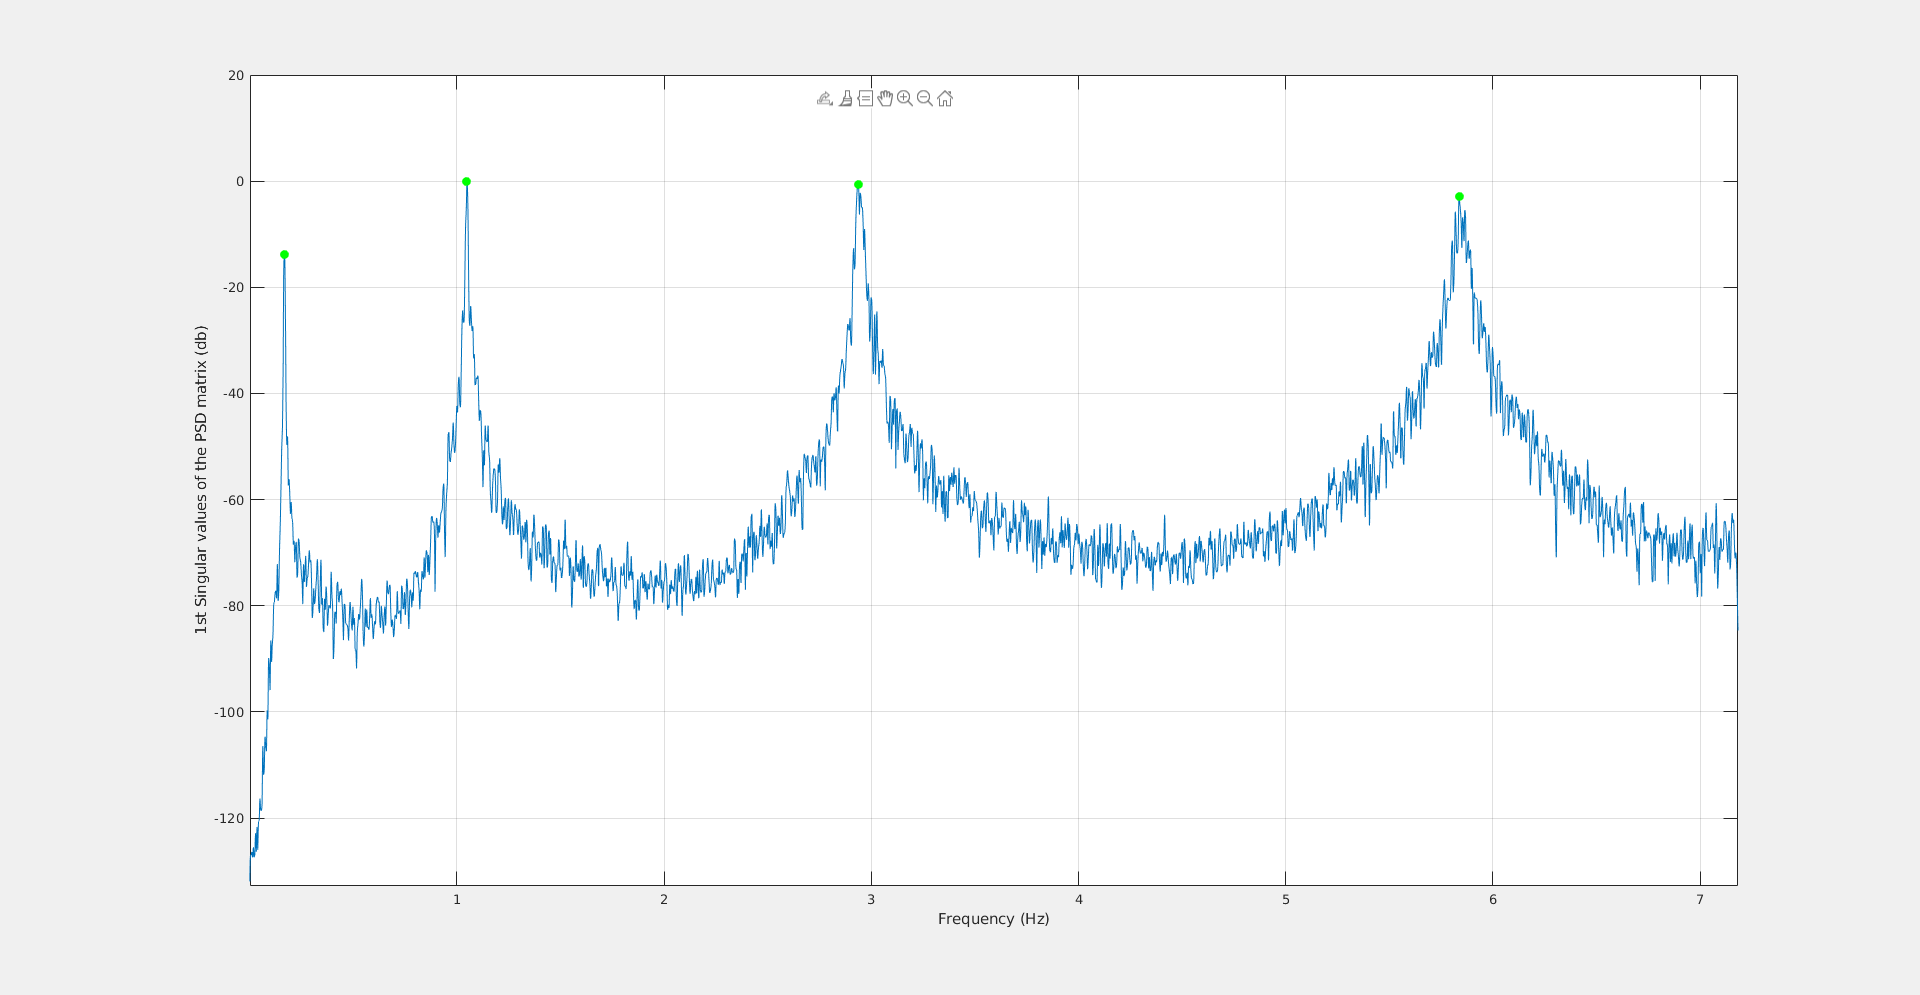

clearvars;close all;clc;
load('beamData.mat')
fn = wn/(2*pi);
Nmodes = numel(fn);
fs = 1/median(diff(t));
rng(1)

tic
[phi_FDD,fn_FDD,zeta] = AFDD(Az,t,Nmodes,'PickingMethod','manual');

toc

Elapsed time is 41.326745 seconds.


### Mode shape visualization

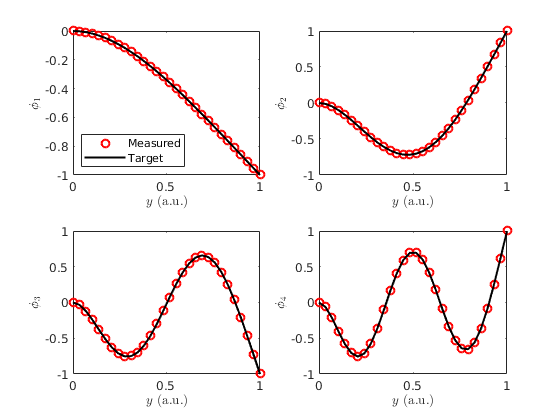

figure
for ii=1:size(phi_FDD),
    subplot(2,2,ii)
    hold on;box on;
    h1 = plot(linspace(0,1,size(phi_FDD,2)),phi_FDD(ii,:),'ro','linewidth',1.5);
    h2 = plot(linspace(0,1,size(phi,2)),-phi(ii,:),'k-','linewidth',1.5);
    xlabel('$y$ (a.u.)','interpreter','latex')
    ylabel(['$\phi_',num2str(ii),'$'],'interpreter','latex')
    if ii==1,
        legend('Measured','Target','location','SouthWest')
    end
end

### Eigen frequencies

disp('left: target eigen frequencies. Right: Measured eigenfrequencies')

left: target eigen frequencies. Right: Measured eigenfrequencies


disp([fn(:),fn_FDD(1:Nmodes)'])

    0.1671    0.1683
    1.0472    1.0483
    2.9323    2.9356
    5.7460    5.8362



disp('left: target damping. Right: Measured damping')

left: target damping. Right: Measured damping


disp([5e-3*ones(Nmodes,1),zeta(:),])

    0.0050    0.0059
    0.0050    0.0042
    0.0050    0.0049
    0.0050    0.0053



## 3 Application of the function AFDD: minimalist automated procedure

Minimalist example with automated procedure

[phi_FDD,fn_FDD,zeta] = AFDD(Az,t,Nmodes);


### Mode shape visualization

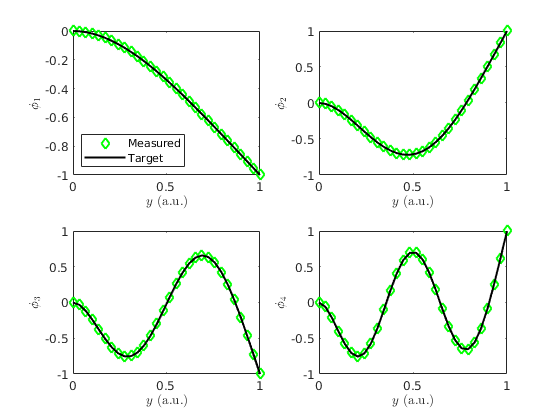

figure
for ii=1:size(phi_FDD),
    subplot(2,2,ii)
    hold on;box on;
    h1 = plot(linspace(0,1,size(phi_FDD,2)),phi_FDD(ii,:),'gd','linewidth',1.5);
    h2 = plot(linspace(0,1,size(phi,2)),-phi(ii,:),'k-','linewidth',1.5);
    xlabel('$y$ (a.u.)','interpreter','latex')
    ylabel(['$\phi_',num2str(ii),'$'],'interpreter','latex')
    if ii==1,
        legend('Measured','Target','location','SouthWest')
    end
end

### Eigen frequencies

disp('left: target eigen frequencies. Right: Measured eigenfrequencies')

left: target eigen frequencies. Right: Measured eigenfrequencies


disp([fn(:),fn_FDD(1:Nmodes)'])

    0.1671    0.1683
    1.0472    1.0483
    2.9323    2.9356
    5.7460    5.8362



disp('left: target damping. Right: Measured damping')

left: target damping. Right: Measured damping


disp([5e-3*ones(Nmodes,1),zeta(:),])

    0.0050    0.0093
    0.0050    0.0039
    0.0050    0.0053
    0.0050    0.0054



## 4 Automated procedure: 2-step analysis

The automated procedure presented here is based on 2 steps but can be reduced to a single step (cf. above) if the signal to noise ratio is low enough:

-  identification of the eigenfrequencies

- Identification of the mode shapes and the damping ratio

An automated selection of the peak is easier  if the spectral density matrix is smoohted by using a relatively short windows made of M points. However, using a low value for M leads to an overestimation of the modal damping ratio unless long records are used. In the present example, the duration of the time series is 20 minutes, which is too short to carry out the automated procedure in one step. Using a low value for M is also more time-consuming. To keep the simulation realistic, the acceleration records are selected for a limited number of points along the beam only.

### First step: determination of the eigenfrequencies

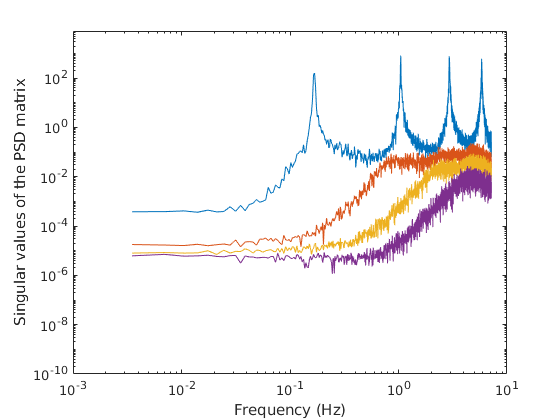

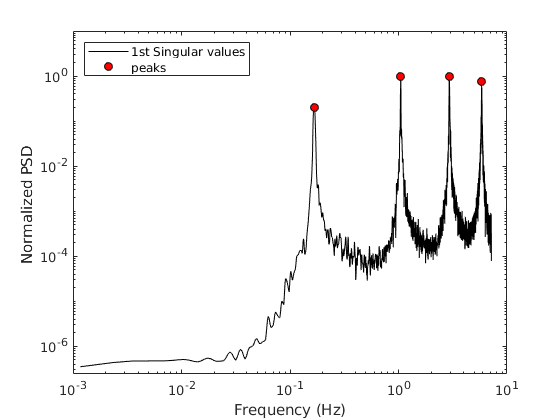

[~,fn_FDD,zeta] = AFDD(Az(1:5:end,:),t,Nmodes,'dataPlot',1);

% The estimated zeta is ca. 10 x larger for the first 2 modes than expected.
% the theoritical and measured eigen frequencies agrees however well!
disp('left: target eigen frequencies. Right: Measured eigenfrequencies')

left: target eigen frequencies. Right: Measured eigenfrequencies


disp([fn(:),fn_FDD(1:Nmodes)'])

    0.1671    0.1683
    1.0472    1.0483
    2.9323    2.9356
    5.7460    5.8362



### Second step: determination of the modal damping ratio

We use a high M value and the eigenfrequencies identified during the first step. We use the option 'dataPlot' to plot intermediate figures, to illustrate the method, and to check the accuracy of the results.

[phi_FDD,fn_FDD,zeta] = AFDD(Az,t,Nmodes,'fn',fn_FDD,'M',8192);

### Mode shape visualization

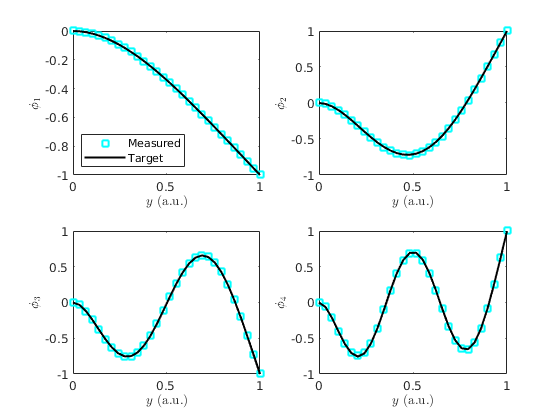

figure
for ii=1:size(phi_FDD),
    subplot(2,2,ii)
    hold on;box on;
    h1 = plot(linspace(0,1,size(phi_FDD,2)),phi_FDD(ii,:),'csq','linewidth',1.5);
    h2 = plot(linspace(0,1,size(phi,2)),-phi(ii,:),'k-','linewidth',1.5);
    xlabel('$y$ (a.u.)','interpreter','latex')
    ylabel(['$\phi_',num2str(ii),'$'],'interpreter','latex')
    if ii==1,
        legend('Measured','Target','location','SouthWest')
    end
end

disp('left: target damping. Right: Measured damping')

left: target damping. Right: Measured damping


disp([5e-3*ones(Nmodes,1),zeta(:),])

    0.0050    0.0050
    0.0050    0.0051
    0.0050    0.0053
    0.0050    0.0045



## 5 Case of user-defined boundaries for the selected peaks.

The boundaries for the selected peaks (lines 209 in the main function AFDD) may not be adapted if the eigenfrequency values range from low to high frequencies. For this reason, it is possible to manually give the upper boundaries (UB) and the lower boundaries(LB) as shown below for the first 4 eigenfrequencies of the beam studied:

% lower boundary for the first four modes (Default: LB = 0.9*fn)
LB = [0.15,0.9,2.8,5.5];
% upper boundary boundary for the first four modes (Default: UB = 0.9*fn)
UB = [0.18,1.15,3.1,6.1];

### Visualization of the boundaries

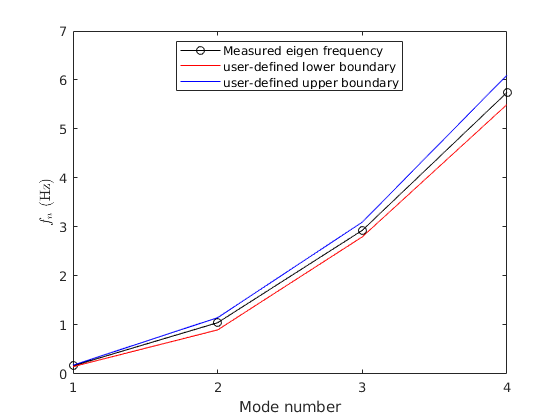

clf;close all;
figure
plot(1:4,fn,'ko-',1:4,LB,'r-',1:4,UB,'b-')
ylabel('$f_n$ (Hz)','interpreter','latex')
legend('Measured eigen frequency','user-defined lower boundary','user-defined upper boundary','location','best')
xlabel('Mode number')
set(gca,'xtick',[1,2,3,4])

 Calculation of the modal parameters with user-defined UBs and LBs

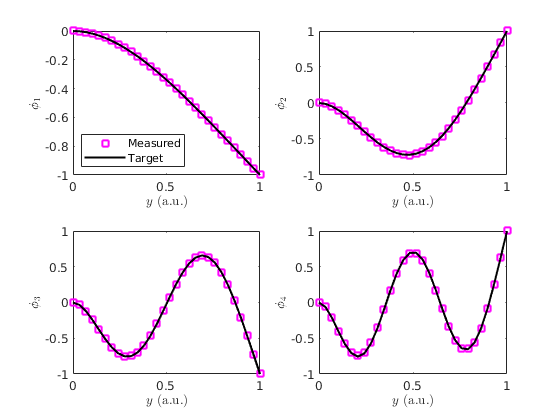

[phi_FDD,fn_FDD,zeta] = AFDD(Az,t,Nmodes,'M',8192,'UB',UB,'LB',LB);

figure
for ii=1:size(phi_FDD),
    subplot(2,2,ii)
    hold on;box on;
    h1 = plot(linspace(0,1,size(phi_FDD,2)),phi_FDD(ii,:),'msq','linewidth',1.5);
    h2 = plot(linspace(0,1,size(phi,2)),-phi(ii,:),'k-','linewidth',1.5);
    xlabel('$y$ (a.u.)','interpreter','latex')
    ylabel(['$\phi_',num2str(ii),'$'],'interpreter','latex')
    if ii==1,
        legend('Measured','Target','location','SouthWest')
    end
end

disp('left: target damping. Right: Measured damping')

left: target damping. Right: Measured damping


disp([5e-3*ones(Nmodes,1),zeta(:),])

    0.0050    0.0057
    0.0050    0.0044
    0.0050    0.0056
    0.0050    0.0049



## 6 Conclusion

The function AFDD was here illustrated with four examples: One manual procedure, and three automatic ones. The modal damping ratios were different for each case because the estimation of the autocorrelation function was done in the time domain using random phases. Random phases were used since the information about the original phases were lost during the calculation of the PSD. Alternative approaches may be more efficient and are welcomed.